img = imread("dimes3.jpg")

img = 2448×3264 uint8 matrix
   122   123   122   117   111   111   115   120   110   111   115   120   116   108   106   111   110   117   117   112   113   117   110    97   103   110   118   121   120   116   113   112   118   119   119   118   116   116   119   121   125   124   122   120   118   116   114   113   115   116
   122   121   117   111   105   104   107   111   110   110   113   116   112   106   108   113   114   119   118   111   113   119   116   106   104   109   116   119   117   114   112   112   111   112   113   113   113   116   120   124   125   124   122   120   119   118   117   117   116   116
   116   115   112   108   104   103   105   108   110   110   111   112   109   105   108   114   120   122   119   112   113   120   121   115   106   110   114   115   115   113   112   112   106   107   109   111   113   116   121   125   121   120   118   117   117   117   119   119   116   116
   105   106   108   110   112   112   112   111   109   111   113  

img = im2gray(img)

img = 2448×3264 uint8 matrix
   122   123   122   117   111   111   115   120   110   111   115   120   116   108   106   111   110   117   117   112   113   117   110    97   103   110   118   121   120   116   113   112   118   119   119   118   116   116   119   121   125   124   122   120   118   116   114   113   115   116
   122   121   117   111   105   104   107   111   110   110   113   116   112   106   108   113   114   119   118   111   113   119   116   106   104   109   116   119   117   114   112   112   111   112   113   113   113   116   120   124   125   124   122   120   119   118   117   117   116   116
   116   115   112   108   104   103   105   108   110   110   111   112   109   105   108   114   120   122   119   112   113   120   121   115   106   110   114   115   115   113   112   112   106   107   109   111   113   116   121   125   121   120   118   117   117   117   119   119   116   116
   105   106   108   110   112   112   112   111   109   111   113  

threshValue = 0.6967

ans = 177.6473

%global threshold calculated from otsu's method
thresh = graythresh(img) * 255

thresh = 143

% calculate the number of true pixels
BW = imbinarize(img, graythresh(img))

BW = 2448×3264 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

nnz(BW)

ans = 594617

% measure of effectiveness of otsu's method
[~, effectivenessMatric] = graythresh(img)

effectivenessMatric = 0.6967

% segment the image using adaptive threshold

BW2 = imbinarize(img, "adaptive")

BW2 = 2448×3264 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

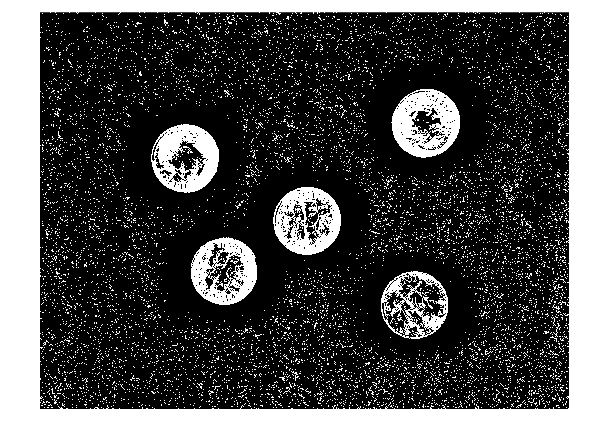

imshow(BW2)